clc;
clear all;
close all;

%%%%%%%%%%%%%%%%%%%%%%%%
% COMMON BLOCK: Load Dataset
%%%%%%%%%%%%%%%%%%%%%%%%
load Dataset_cell2cell.mat
Dataset = rmmissing(Dataset);

% Extract distance and features
dist = table2array(Dataset(:, 1));
sequence = table2array(Dataset(:, 2:end));

% Calculate slope, amplitude, and peak location
window = 2;
slope = sequence(:, window:end) - sequence(:, 1:end-window+1);
[peak, loc] = min(slope, [], 2);

% Update Dataset
Dataset = array2table([dist, peak, loc], 'VariableNames', {'Var1', 'Feature1', 'Feature2'});

% Partition Data for NN
rng("default"); % For reproducibility
cvp1 = cvpartition(size(Dataset, 1), "Holdout", 1/10);
testTbl = Dataset(test(cvp1), :);
remainingTbl = Dataset(training(cvp1), :);
cvp2 = cvpartition(size(remainingTbl, 1), "Holdout", (3/10) / (1 - 1/10));
validationTbl = remainingTbl(test(cvp2), :);
trainTbl = remainingTbl(training(cvp2), :);

% Train Neural Network
Mdl = fitrnet(trainTbl, "Var1", "Standardize", true, ...
    "ValidationData", validationTbl, 'ValidationPatience', 10, ...
    "Verbose", 1, ...
    "LayerSizes", [2], ...
    "Activations", 'sigmoid', 'LossTolerance', 1e-9);

|==========================================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  | Validation | Validation |
|            |            |            |            | Time (sec) | Loss       | Checks     |
|==========================================================================================|
|           1|    0.012043|    0.218233|    0.252241|    0.024201|    0.011937|           0|
|           2|    0.000325|    0.004363|    0.087316|    0.009499|    0.000337|           0|
|           3|    0.000299|    0.004758|    0.004193|    0.013433|    0.000314|           0|
|           4|    0.000169|    0.003115|    0.040902|    0.004115|    0.000184|           0|
|           5|    0.000157|    0.001291|    0.009061|    0.012507|    0.000168|           0|
|           6|    0.000150|    0.002356|    0.010411|    0.002006|    0.000157|           0|
|           7|    0.000142|    0.004091|    0.012697|    0.000276|    


% LIME Explainer
explainer = lime(Mdl, trainTbl, 'NumImportantPredictors', 2);

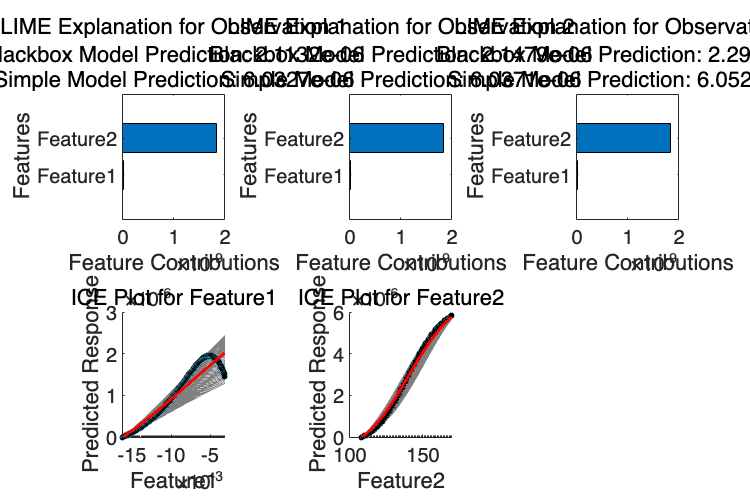

numObservations = 3;
testObservations = testTbl(1:numObservations, :);

%%%%%%%%%%%%%%%%%%%%%%%%
% BLOCK I: Combined Figure with Subplots
%%%%%%%%%%%%%%%%%%%%%%%%
figure('Position', [100, 100, 1200, 800]);
tiledlayout(2, 3, 'TileSpacing', 'Compact', 'Padding', 'loose');

% Upper Part: LIME Plots
for i = 1:numObservations
    nexttile(i);
    observation = testObservations(i, :);
    results = fit(explainer, observation, 'NumNeighbors', 500);
    plot(results);
    title(sprintf('LIME Explanation for Observation %d', i), 'FontSize', 24, 'FontWeight', 'normal');
    xlabel('Feature Contributions', 'FontSize', 20);
    ylabel('Features', 'FontSize', 20);
    set(gca, 'FontSize', 20); % Tick label font size
end

% Upper part general title
%sgtitle('LIME Explanations for Selected Observations', 'FontSize', 24, 'FontWeight', 'normal');

% Lower Part: ICE Plots
% Title for lower row

% Partial Dependence for Feature1
nexttile(4);
plotPartialDependence(Mdl, "Feature1", trainTbl, "Conditional", "centered");
title('ICE Plot for Feature1', 'FontSize', 20, 'FontWeight', 'normal');
xlabel('Feature1', 'FontSize', 20);
ylabel('Predicted Response', 'FontSize', 20);
set(gca, 'FontSize', 20); % Tick label font size

% Partial Dependence for Feature2
nexttile(5);
plotPartialDependence(Mdl, "Feature2", trainTbl, "Conditional", "centered");
title('ICE Plot for Feature2', 'FontSize', 20, 'FontWeight', 'normal');
xlabel('Feature2', 'FontSize', 20);
ylabel('Predicted Response', 'FontSize', 20);
set(gca, 'FontSize', 20); % Tick label font size